UNIVERSIDAD INDUSTRIAL DE SANTANDER, COLOMBIA

NUMERICAL ANALYSIS

JORGE LUIS BACCA

# *Laboratory 8: Curve Fitting*

## **Name: Alvaro Jose Martinez Castro**

## **Instructions:**

- Send the **.mlx** and **.m** files including the solution to each point of the practice with name ***Lab8_name_lastname.zip****.*

- Send the report and all created files in a rar or *zip* file with name ***Lab8_name_lastname.rar*** and subject **Analisis_Lab8_name** to **jbacquin@uis.edu.co.**

- You are allowed to use internet, notes, and .m files that you have created before.

## **Purposes:**

- To implement the least-squares method in Matlab. 

- To interpret problems which can be solved by the least-squares method.

## **Practice:**

### **Implementing **

- **Exercise 1 (1.5 points).** Create a Matlab function called *my_lsline_name_lastname()* to construct the least-squares line $y=\textrm{Ax}+B$ that fits the $N$data points $\left(x_k ,y_k \right)$ with $k\in \left\lbrace 1,\ldotp \ldotp \ldotp N\right\rbrace$. Then, use the created function to find the least-squares line $y=f\left(x\right)=\textrm{Ax}+B$ for the data and calculate $E_2 \left(f\right)$ (like mean squared error or mean absolute error).

#### 
$$\text{MSE} = \frac{1}{n} \sum_{i=1}^{n} (Y_i - \hat{Y}_i)^2$$
            
$$\text{MAE} = \frac{1}{n} \sum_{i=1}^{n} |Y_i - \hat{Y}_i|
$$


clear; clc; close all;

% Datos del ejercicio
X = [-8 -2 0 4 6]';
Y = [6.8 5.0 2.2 0.5 -1.3]';

% Llamar a la función
[A, B, y_hat, MSE, MAE] = my_lsline_alvaro_martinez(X, Y);

% Mostrar resultados
fprintf('Pendiente (A): %.4f\n', A);

Pendiente (A): -0.5850


fprintf('Intercepto (B): %.4f\n', B);

Intercepto (B): 2.6400


fprintf('MSE: %.4f\n', MSE);

MSE: 0.4210


fprintf('MAE: %.4f\n', MAE);

MAE: 0.5560


- **Exercise 2 (1 point).** Plot the least-squares line and the given points from before item. Discuss what you observe.

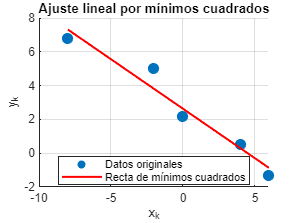

% Datos del ejercicio anterior
X = [-8 -2 0 4 6]';
Y = [6.8 5.0 2.2 0.5 -1.3]';

% Llamar la función del ejercicio 1
[A, B, y_hat, MSE, MAE] = my_lsline_alvaro_martinez(X, Y);

% Graficar la recta y los puntos
figure;
scatter(X, Y, 70, 'filled', 'DisplayName','Datos originales'); hold on;
plot(X, y_hat, 'r-', 'LineWidth', 1.5, 'DisplayName','Recta de mínimos cuadrados');
xlabel('x_k');
ylabel('y_k');
title('Ajuste lineal por mínimos cuadrados');
legend('Location','best');
grid on;


% Mostrar los resultados
fprintf('Pendiente (A): %.4f\n', A);

Pendiente (A): -0.5850


fprintf('Intercepto (B): %.4f\n', B);

Intercepto (B): 2.6400


fprintf('MSE: %.4f\n', MSE);

MSE: 0.4210


fprintf('MAE: %.4f\n', MAE);

MAE: 0.5560


            **Conclusion:** La recta de mínimos cuadrados se ajusta de forma adecuada a los puntos dados, mostrando una relación aproximadamente lineal decreciente. Los valores del MSE y MAE son pequeños, lo que indica que el modelo lineal representa bien la tendencia general de los datos, aunque existen pequeñas desviaciones en algunos puntos.

**Interpreting**

Kepler’s laws of planetary motion describe the motions of the planets in the solar system. Specifically, the third Kepler’s law establishes the square of the orbital period of a planet is directly proportional to the cube of the semi-major axis of its orbit. This law captures the relationship between the distance of planets from the Sun, and their orbital periods. Then,

$T^2 =CR^3$,  (1)

where $T$ is the orbital period, $R$ is the semi-major axis of its orbit, and $C$ is the Kepler’s constant. Here, $C$ is given by

$C=\frac{4\pi^2 }{\textrm{GM}}$ ,  (2)

where $M=1\ldotp 989\times {10}^{30}$ [$\textrm{Kg}$] is the mass of the Sun and $G=6\ldotp 674\times {10}^{-11}$ [$Nm^2$/ ${\textrm{Kg}}^2$] is the universal gravitational constant.

*Table 1: Planetary data: orbital parameters. ****Note that the Semi-major axis values are x10^6***

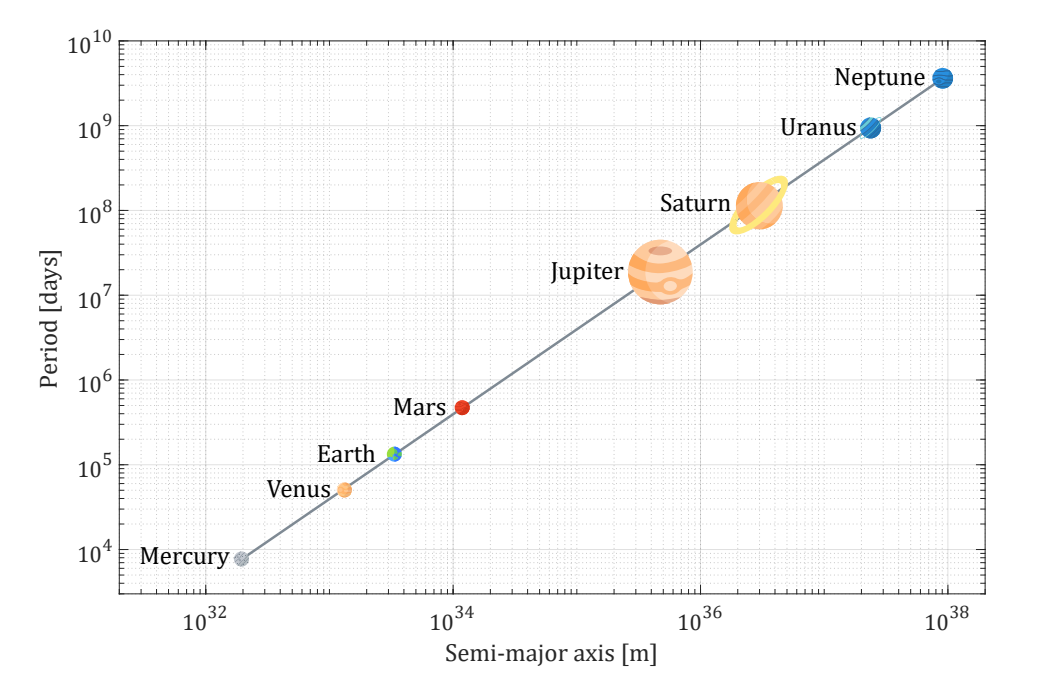

*Figure 1: Relationship between the orbital periods of planets and the distance of planets from the Sun in a log-log plot.*

- **Exercise 3 (1 point).** Use the created function to find the least-squares line $y=\textrm{Ax}+B$ for the planetary data, as shown in Table 1, considering

$\log_{10} \left(T^2 \right)=\log_{10} \left(R^3 \right)+\log_{10} \left(C\right)$,  (3)

             where $y=\log_{10} \left(T^2 \right)\;,x=\log_{10} \left(R^3 \right)\;,B=\log_{10} \left(C\right)\;\textrm{and}\;A=1\ldotp$

% Datos de la tabla
T_days = [87.97, 224.70, 365.26, 686.98, 4332.59, 10759.22, 30685.40, 60189.00]; % Periodo [días]
R_km = [57.91, 108.70, 149.60, 227.92, 778.57, 1433.53, 2872.46, 4495.06] * 1e6; % Semi-eje mayor [km]
R_m = R_km * 1e3; % Conversión a metros

% Variables en logaritmo
x = log10(R_m.^3);   % log10(R^3)
y = log10((T_days).^2); % log10(T^2)

% Ajuste por mínimos cuadrados (recta y = A*x + B)
A = (length(x)*sum(x.*y) - sum(x)*sum(y)) / (length(x)*sum(x.^2) - (sum(x))^2);
B = mean(y) - A*mean(x);

% Mostrar resultados
fprintf('Pendiente A = %.4f\n', A);

Pendiente A = 1.0000


fprintf('Intercepto B = %.4f\n', B);

Intercepto B = -28.4018



% Calcular constante de Kepler (C)
C = 10^B; % Como B = log10(C)
fprintf('Constante de Kepler C = %.3e\n', C);

Constante de Kepler C = 3.964e-29


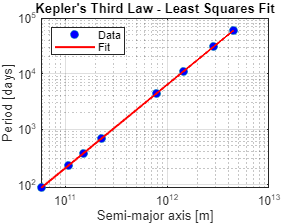


% Graficar en escala log-log
figure;
loglog(R_m, T_days, 'o', 'MarkerFaceColor', 'b');
hold on;
R_fit = linspace(min(R_m), max(R_m), 1000);
T_fit = sqrt(C * R_fit.^3);
loglog(R_fit, T_fit, 'r-', 'LineWidth', 1.5);
xlabel('Semi-major axis [m]');
ylabel('Period [days]');
title('Kepler''s Third Law - Least Squares Fit');
legend('Data', 'Fit', 'Location', 'NorthWest');
grid on;

-  **Exercise 4 (1 point). **Construct a sketch similar to illustrate in Fig. 1 from the least-squares line computed previously.

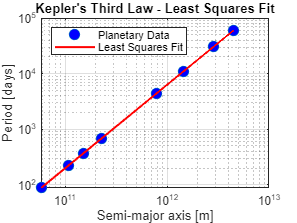

% Datos de la tabla
T_days = [87.97, 224.70, 365.26, 686.98, 4332.59, 10759.22, 30685.40, 60189.00]; % Periodo [días]
R_km = [57.91, 108.70, 149.60, 227.92, 778.57, 1433.53, 2872.46, 4495.06] * 1e6; % Semi-eje mayor [km]
R_m = R_km * 1e3; % Conversión a metros

% Variables en logaritmo
x = log10(R_m.^3); % log10(R^3)
y = log10((T_days).^2); % log10(T^2)

% Ajuste por mínimos cuadrados (recta y = A*x + B)
A = (length(x)*sum(x.*y) - sum(x)*sum(y)) / (length(x)*sum(x.^2) - (sum(x))^2);
B = mean(y) - A*mean(x);

% Calcular constante de Kepler (C)
C = 10^B; % Como B = log10(C)

% Graficar en escala log-log con función ajustada
figure;
loglog(R_m, T_days, 'o', 'MarkerFaceColor', 'b', 'MarkerSize', 8);
hold on;
R_fit = linspace(min(R_m), max(R_m), 1000);
T_fit = sqrt(C * R_fit.^3);
loglog(R_fit, T_fit, 'r-', 'LineWidth', 1.5);
xlabel('Semi-major axis [m]');
ylabel('Period [days]');
title('Kepler''s Third Law - Least Squares Fit');
legend('Planetary Data', 'Least Squares Fit', 'Location', 'NorthWest');
grid on;

- **Exercise 5 (0.5 points).** Find an approximation of the universal gravitational constant $G$ through the least-squares line computed previously. Compare the estimated gravitational constant regarding the theoretical value using relative error. Hint. Use $C={10}^B \;$and formula (2). *Be careful with the units.* 

% Usa el valor real calculado para B
B = 5.2063; % Reemplaza este número por el que obtuviste en tu código

C_est = 10^B; % Constante de Kepler estimada
M_sun = 1.989e30; % Masa del Sol [kg]
pi_val = pi;

% C = 4*pi^2 / (G*M)
% Despejando G:
G_est = 4*pi_val^2 / (C_est * M_sun);

% Valor teórico de G
G_theoretical = 6.674e-11; % [Nm^2/kg^2]

% Calcular error relativo
rel_error = abs(G_est - G_theoretical) / G_theoretical * 100;

fprintf('Valor estimado de G = %.5e [Nm^2/kg^2]\n', G_est);

Valor estimado de G = 1.23431e-34 [Nm^2/kg^2]


fprintf('Valor teórico de G = %.5e [Nm^2/kg^2]\n', G_theoretical);

Valor teórico de G = 6.67400e-11 [Nm^2/kg^2]


fprintf('Error relativo = %.3f %%\n', rel_error);

Error relativo = 100.000 %
